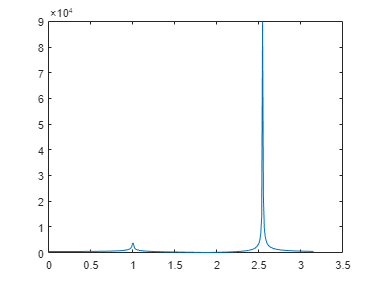


clear all
h = 2e-3;
z = h+eps ;
er = 10 ;
freq = 20.*1e9 ;
freqn = linspace(freq,1e9,500);
lambdan=3e8./freqn ;
lambda = 3e8./freq ;
k0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,303) ;
[D] = Den_GroundSlab(k0,er,h,krho,freq,'TE') ;

plot(krho./k0,abs(D))


krhoginitial = 1.8848

krhoginitial = 1.8848


for ii = 1:length(freqn)-1
    if ii==1
        krhog = krhoginitial ;
    end
        krhoi(ii) = findpropc(freqn(ii),er,h,krhog,'TE','GroundSlab');
        krhog = krhoi(ii) ;
end

Unrecognized function or variable 'Dkrhog'.

Error in findpropc (line 21)
krho = krhog - Dkrhog./Dprime ;

k0=2*pi./lambdan
plot(freqn,abs(krholoop))